clc
clear
% path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\pixel_videos_directioned_Iqtau\';
% filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\finn_videos_original_fps_Analysis\';
filename='rescale_60feet_100000961607_cropped_deshaked_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
load(input)

angle_num=size(angle_Iqtau,1);
qVec=1:size(angle_Iqtau,2);
q_num=size(angle_Iqtau,2);
tVec=1:size(angle_Iqtau,3);
t_num=size(angle_Iqtau,3);

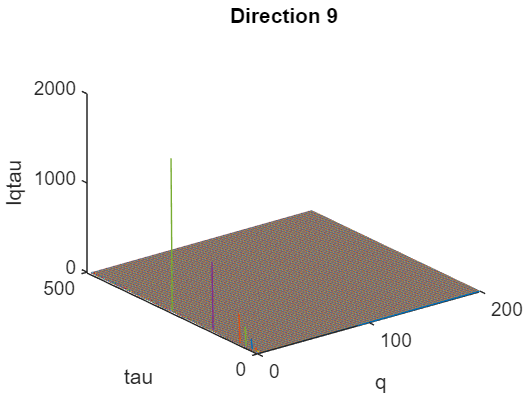

q_max=200;
figure()
plot3(repmat((qVec(1:q_max))',1,t_num),repmat((tVec),q_max,1),squeeze(angle_Iqtau(5,(1:q_max),:)))
% xlim([0 200])
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 9')

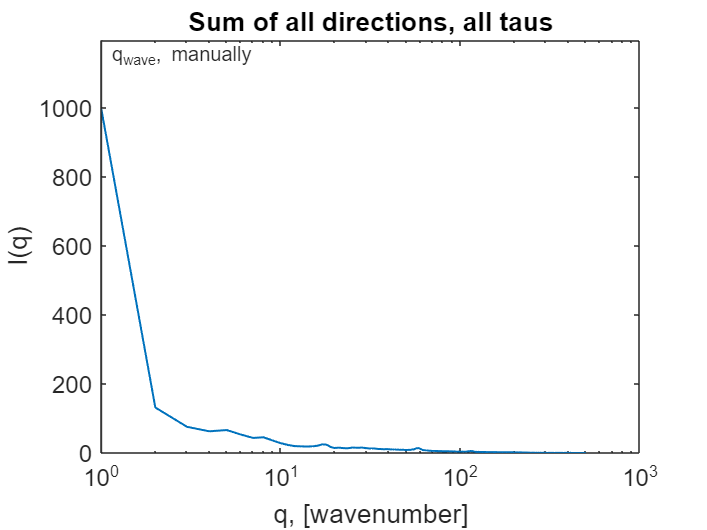

wavelength=1;
scale=1024;
q_max=500;
plotIq_all_dirc_all_tau(angle_Iqtau,path,wavelength,scale,q_max)

tau=16;
wavenumber=5;
fps=29.97;
scale=1024;
q_max=500;

% plotIq_all_dirc_selected_tau(angle_Iqtau,tau,path,wavenumber,scale,q_max,fps)
qVec=1:size(angle_Iqtau,2);
fig=figure();
y=sum(angle_Iqtau(:,1:q_max,tau),1);

wavenumber = 1024/(150/6.38*9.07);
wavenumber_sin = 1024/(150/6.38*0.37)

wavenumber_sin = 117.7139

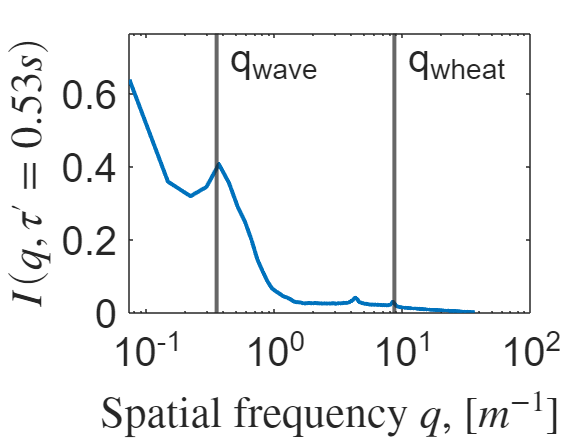

%%  for Finnland wheat videos
semilogx(qVec(1:q_max)*2*pi/scale*11.8961,squeeze(y),"LineWidth",2)
hxl = xline(wavenumber*2*pi/scale*11.8961,'-',{'q_{wave}'},'LabelOrientation','horizontal','LineWidth',2);

hxl_single_wheat = xline(wavenumber_sin*2*pi/scale*11.8961,'-',{'q_{wheat}'},'LabelOrientation','horizontal','LineWidth',2);
hxl.FontSize = 20;
hxl_single_wheat.FontSize = 20;
ylim([0 1.2*max(y)]);
set(gca,'fontsize', 20); 
%%   for Finnland wheat videos
xlabel('Spatial frequency $q$, [$m^{-1}$]','Interpreter','latex')
ylabel(['$I(q,\tau''=' num2str(round(tau/fps,2)) 's)$'],'Interpreter','latex')
xticks([10^(-1) 10^0 10^1 10^2])

q = 8;
x = tVec/fps;
y = squeeze(sum(angle_Iqtau(:,q,:),1));
figure()
% plot(x,y,'o','LineWidth',2)


exclude=x>1.5;

% y = A*(1-exp(cos(2*pi*v*x))).*exp(x/tau_c)+B;
ft = fittype( 'fit_function(x,A,v,tau_c,B)' );
% StartPoint order: A,B,tau_c,v
f = fit( x(:), y, ft, 'StartPoint', [0.05, 0.3, -1, 1], 'Exclude', exclude)

f =      General model:
     f(x) = fit_function(x,A,v,tau_c,B)
     Coefficients (with 95% confidence bounds):
       A =      0.1323  (0.1173, 0.1473)
       B =      0.1828  (0.1768, 0.1888)
       tau_c =     -0.7679  (-0.9223, -0.6134)
       v =      0.8965  (0.8651, 0.9279)

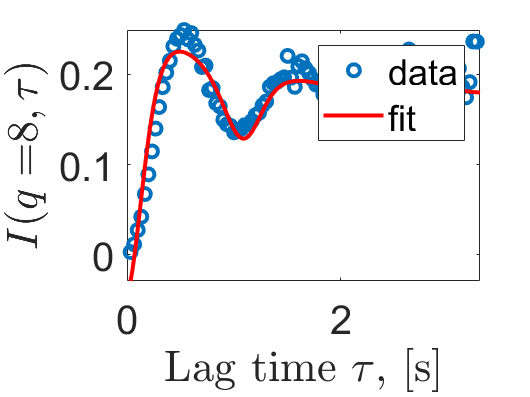

h=plot( f, x, y ,"o") ;
h(1).LineWidth=2;
h(2).LineWidth=2;

legend('data','fit')
xlim([0 3.3]);
set(gca,'fontsize', 20); 
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel(['$I(q=$' int2str(q) '$,\tau)$'],'Interpreter','latex')

q = 60;
x = tVec/fps;
y = squeeze(sum(angle_Iqtau(:,q,:),1));
figure()
% plot(x,y,'o','LineWidth',2)


exclude=x>1.5;

% y = A*(1-exp(cos(2*pi*v*x))).*exp(x/tau_c)+B;

ft = fittype('fit_function(x,A,v,tau_c,B)');
tau_c_fixed = -0.7679;
v_fixed = 0.8965;
lower_bounds = [ -Inf -Inf tau_c_fixed-0.5 v_fixed ];
upper_bounds = [ Inf Inf tau_c_fixed v_fixed ];
fit_options = fitoptions('Method', 'NonlinearLeastSquares',...
                         'Lower', lower_bounds,...
                         'Upper', upper_bounds,...
                         'StartPoint', [0.05, 0.3, -1, 1],...
                         'Exclude', exclude);
% StartPoint order: A,B,tau_c,v
f = fit( x(:), y, ft, fit_options)

f =      General model:
     f(x) = fit_function(x,A,v,tau_c,B)
     Coefficients (with 95% confidence bounds):
       A =     0.01746  (0.006153, 0.02876)
       B =     0.04344  (0.03819, 0.04869)
       tau_c =     -0.7679  (fixed at bound)
       v =      0.8965  (fixed at bound)

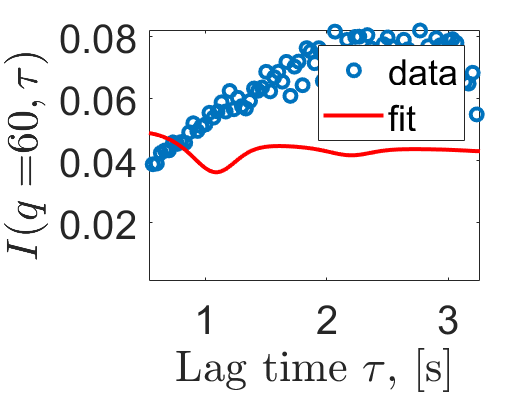

h=plot( f, x, y ,"o") ;
h(1).LineWidth=2;
h(2).LineWidth=2;

legend('data','fit')
xlim([0 3.3]);
set(gca,'fontsize', 20); 
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel(['$I(q=$' int2str(q) '$,\tau)$'],'Interpreter','latex')

q = 5;
fps = 29.97;
x = tVec/fps;
y = squeeze(sum(angle_Iqtau(:,q,:),1));
figure()
% plot(x,y,'o','LineWidth',2)


exclude=x>1;

% y = A*(1-exp(cos(2*pi*v*x))).*exp(x/tau_c)+B;

ft = fittype('fit_function(x,A,v,tau_c,B)');
% tau_c_fixed = -0.7679;
% v_fixed = 0.8965;
% lower_bounds = [ -Inf -Inf tau_c_fixed-0.5 v_fixed ];
% upper_bounds = [ Inf Inf tau_c_fixed v_fixed ];
fit_options = fitoptions('Method', 'NonlinearLeastSquares',...
                             'StartPoint', [0.05, 0.3, -1, 1],...
                         'Exclude', exclude);
%                          'Lower', lower_bounds,...
%                          'Upper', upper_bounds,...

% StartPoint order: A,B,tau_c,v
f = fit( x(:), y, ft, fit_options)

f =      General model:
     f(x) = fit_function(x,A,v,tau_c,B)
     Coefficients (with 95% confidence bounds):
       A =      0.1772  (0.1564, 0.198)
       B =      0.2767  (0.263, 0.2905)
       tau_c =       -2670  (-2.929e+06, 2.924e+06)
       v =      0.7695  (0.7469, 0.7922)

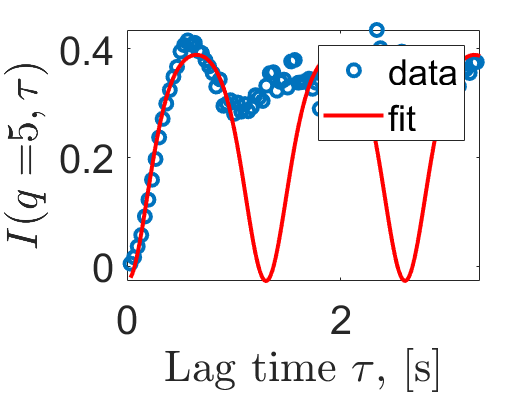

h=plot( f, x, y ,"o") ;
h(1).LineWidth=2;
h(2).LineWidth=2;

legend('data','fit')
xlim([0 3.3]);
set(gca,'fontsize', 20); 
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel(['$I(q=$' int2str(q) '$,\tau)$'],'Interpreter','latex')

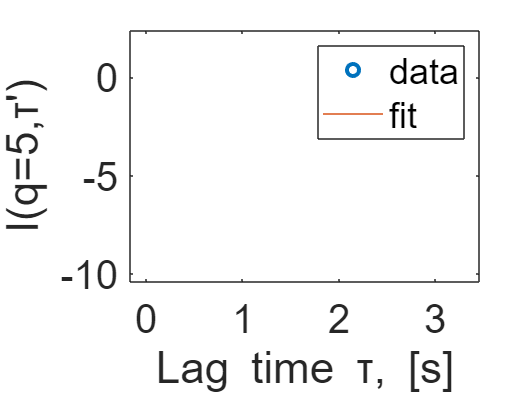

q = 5;
x = tVec/10;
y = squeeze(sum(angle_Iqtau(:,q,:),1));
figure()
plot(x,y,'o','LineWidth',2)
hold on
% StartPoint order: A,B,tau_c,v
A = 5.20;
B = 0.33;
tau_c = -0.5;
v = 1;
x_th = 0:0.01:3.3;
y_th = A*(1-exp(cos(2*pi*v*x_th))).*exp(x_th/tau_c)+B;
plot(x_th, y_th) 

legend('data','fit')
xlim([0 3.3]);
set(gca,'fontsize', 20); 
xlabel('Lag time \tau, [s]','Interpreter','tex')
ylabel(['I(q=' int2str(q) ',\tau'')'],'Interpreter','tex')

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\finn_videos_original_fps_Analysis\';
filename='rescale_60feet_100000961607_cropped_deshaked_nonAvgIqtau.mat';
input=[path filename];
load(input);

Error using load
Cannot read file \\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\finn_videos_original_fps_Analysis\rescale_60feet_100000961607_cropped_deshaked_nonAvgIqtau.mat.

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\finn_videos_Analysis\';
filename='rescale_fps10_60feet_100000961607_cropped_deshaked_nonAvgIqtau.mat';
input=[path filename];
load(input);

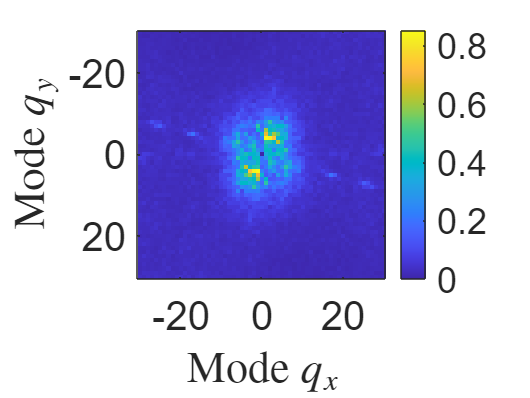

theta=0;
wavenumber=3;
scale=1024;
q_range=30;
tau=5;
plotFFTdifference(nonAvgIqtau,theta,wavenumber,scale,q_range,tau,path)

tau=3;
scale=1024;
wavenumber=3;
q_max=q_num;
plotIq_all_dirc_selected_tau(angle_Iqtau,tau,path,wavenumber,scale,q_max)

figure()
t=16;
q_max=100;
for i=1:angle_num/4
    y=sum(angle_Iqtau(i:i+3,8,t));
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

figure()
clf
t=10;
q_max=100;
for i=1:angle_num
    y=angle_Iqtau(i,1:q_max,t);
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

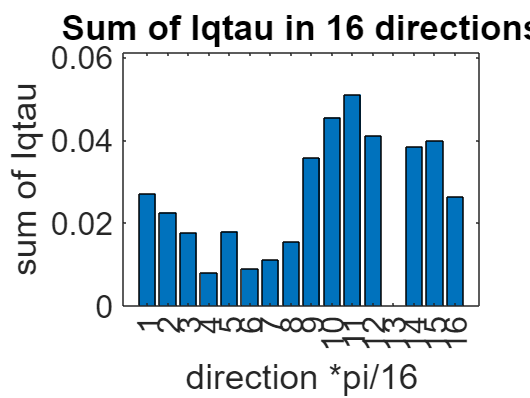

figure()
y=squeeze(sum(sum(angle_Iqtau(:,5,tau),2),3));
bar(1:angle_num,y);
xticks(1:angle_num)
ylim([0 1.2*max(y)])
xlabel('direction *pi/16')
ylabel('sum of Iqtau')
title('Sum of Iqtau in 16 directions')
set(gca,'fontsize', 16);

figure()
% q=3;
q=3;
y=squeeze(sum(sum(angle_Iqtau(:,q,:),2),3));
bar(1:angle_num,y);
xticks(1:angle_num)
ylim([0 1.2*max(y)])
xlabel('direction *pi/16')
ylabel('sum of Iqtau')
title(['Sum of Iqtau in 16 directions for q=' num2str(q)])
set(gca,'fontsize', 16);

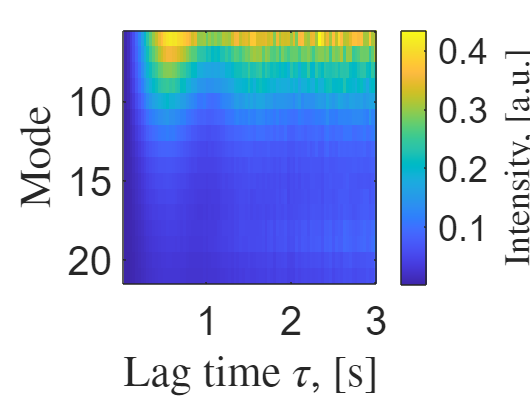

figure()
q_max=20;
tau_max=90;
imagesc(squeeze(sum(angle_Iqtau(:,5:q_max,1:tau_max),1)));
% Set x and y tick positions
xticks([0,30,60,90]);
yticks([0,5,10,15]);
axis square;

% Set x and y tick labels
xticklabels({'0','1', '2', '3'});
yticklabels({'5', '10', '15', '20'});
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel('Spatial frequency $q$, [$m^{-1}$]','Interpreter','latex')
ylabel('Mode','Interpreter','latex')
c = colorbar();
c.Label.String = 'Intensity, [a.u.]';
c.Label.Interpreter = 'latex';
set(gca,'fontsize', 20);